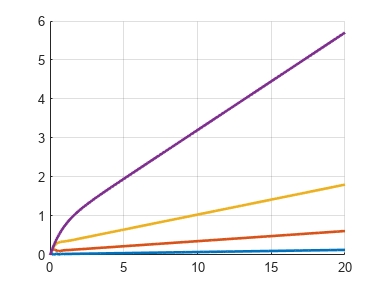

T = (0:0.0001:20)';       
%g = 0.5.*(T.^2);
%g = 4*ones(size(T));
g =  T;
g_signal = [T, g];        

K_list = [120  25  8  2];

figure;
hold on;
grid on;

colors = lines(length(K_list)); % +1 để chừa màu cho mô hình thứ hai
legends_text_y = cell(1, length(K_list)+1);
legends_text_e = cell(1, length(K_list));

for i = 1:length(K_list)

    % gán T vào base workspace để Simulink dùng
    k = K_list(i);
    assignin('base', 'k', k);

    % chạy mô hình thứ nhất (ví dụ bài 2 - có block Transfer Fcn [1 0]/[T 1])
    simOut = sim('bai311', 'ReturnWorkspaceOutputs', 'on');
    % đổi 'ex1_closed' thành tên file simulink của bài 2 của bạn

    % lấy dữ liệu y_out xuất từ To Workspace
    y_struct = simOut.get('y_out');   % nếu biến khác tên, đổi ở đây
    t = y_struct.time;
    y = y_struct.signals.values;

    % найдем ошибку
    e = g - y;

    % vẽ đường cho T hiện tại
    %plot(t, y, 'LineWidth', 2, 'Linestyle', '-', 'Color', colors(i,:));

    % рисовать график ошибки
    plot(t, e, 'LineWidth', 2, 'Linestyle','-', 'Color', colors(i,:));

    % ghi chú legend
    %legends_text_y{i} = sprintf('k = %.1f', K_list(i));

    legends_text_e{i} = sprintf('k = %.1f', K_list(i));
end


%plot(T, g, 'Linewidth', 2, 'Linestyle', ':', 'Color', 'black');
%legends_text{end} = 'g(t)';

## PHẦN 3: trang trí chung

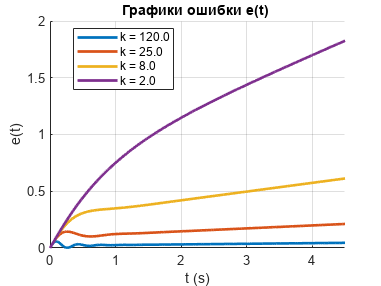

xlim([0, 4.5]); ylim([0, 2]);
xlabel('t (s)');
ylabel('e(t)');
title('Графики ошибки e(t) ');
legend(legends_text_e, 'Location', 'best')
hold off;